%code to threshold the camera videos
vidObj = VideoReader('Video_05-Jul-2022_10-08-16.mp4');

%set the current time
vidObj.CurrentTime = 98;

%video object data
s = struct('vdata',zeros(vidObj.Height,vidObj.Width,3,'uint8'));

k = 1;
while vidObj.CurrentTime <= 125
    s(k).cdata = readFrame(vidObj);
    k = k+1;
end
whos s

  Name      Size                  Bytes  Class     Attributes

  s         1x811            3193004976  struct              



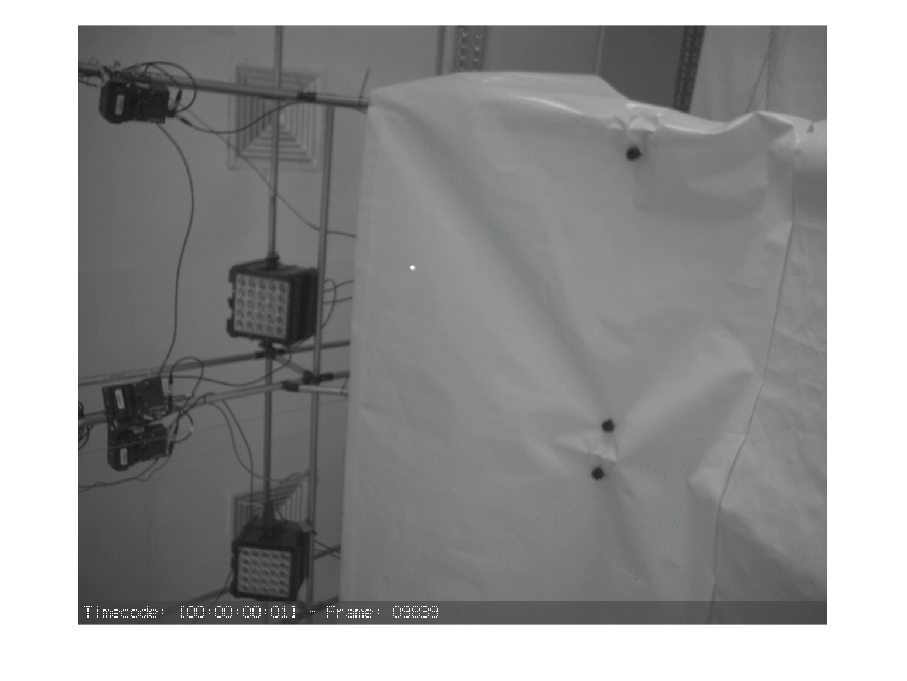

%read the video frames
imshow(s(15).cdata)

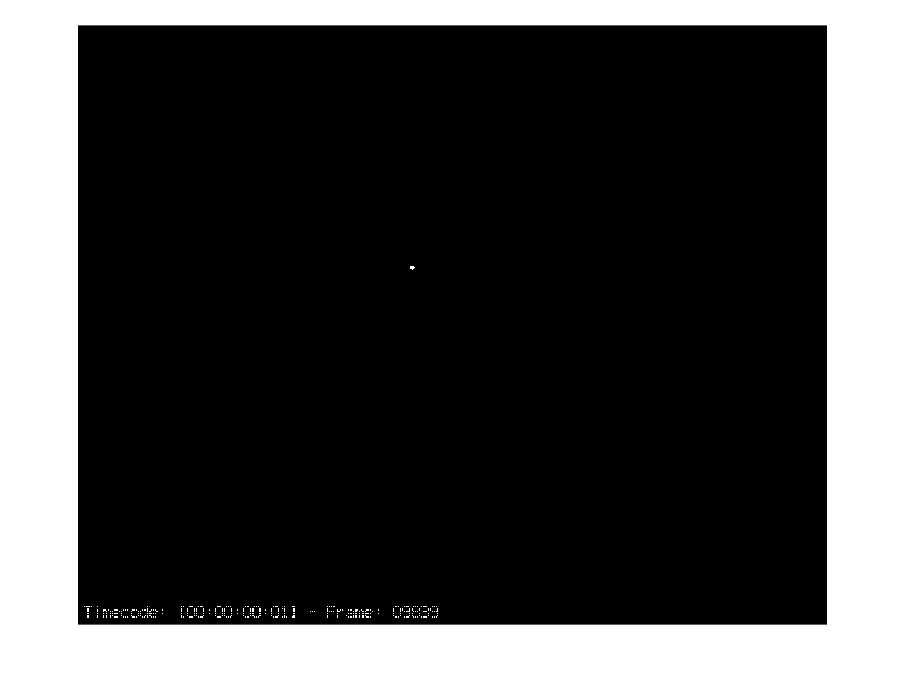

%image data
imData = s(15).cdata;

% %threshed image
% BW = imbinarize(imData(:,:,1));
% 
% imshow(BW)
imThresh = laserThresh(imData);
imshow(imThresh)